# Trabajo practico N°8

# Controladores PID

### Ejercicio 1

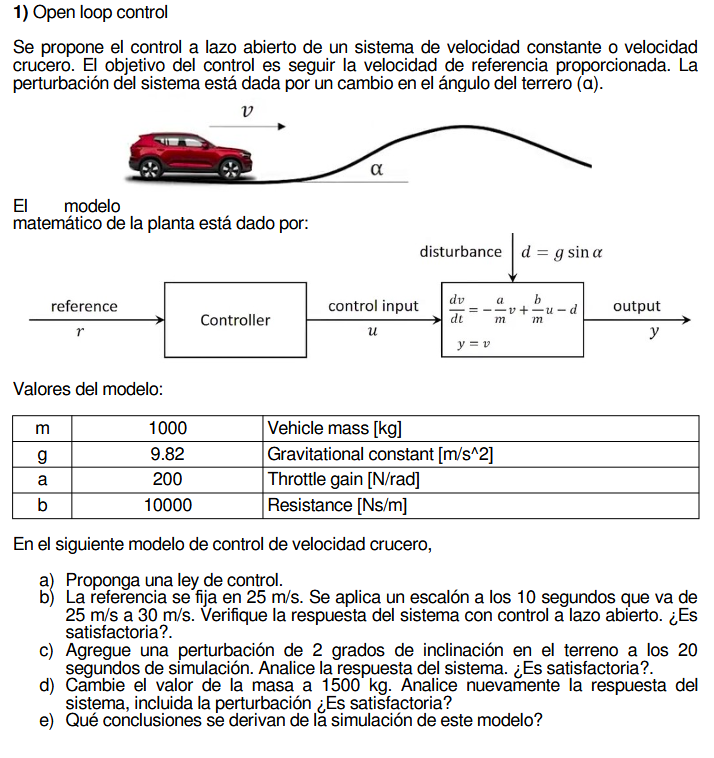

Se realiza una modificacion del modelo de la planta, ya que el análisis dimensional no es consistente, por lo que el modelo de la planta es:


$$\frac{dv}{dt}=-\frac{b}{m}v+\frac{a}{m}u-d\\
y=v$$
 

Cuando se requiere de una velocidad crucero, esta debe ser *constante* por lo tanto, para comenzar formulamos la ecuacion de la planta en estado estacionario

syms m g beta b v u r d alpha t
eqn = 0 == -(b/m)*v + (beta/m)*u;
u_control = solve(eqn,u);
u_control

$$u\_control = \frac{b\,v}{\beta }$$

Luego, la velocidad es justamente nuestra referencia

eqn = 0 == -(b/m)*r + (beta/m)*u;
u_control = solve(eqn,u);
u_control

$$u\_control = \frac{b\,r}{\beta }$$

Lo queda una ley de control de tipo: $u=K_{ol}\cdot r$

m = 1000;   % Masa [kg]
g = 9.82;   % Gravedad [m/s^2]
a = 200;    % Ganancia del acelerador [N/rad] 
b = 10000;  % Resistencia [Ns/m]


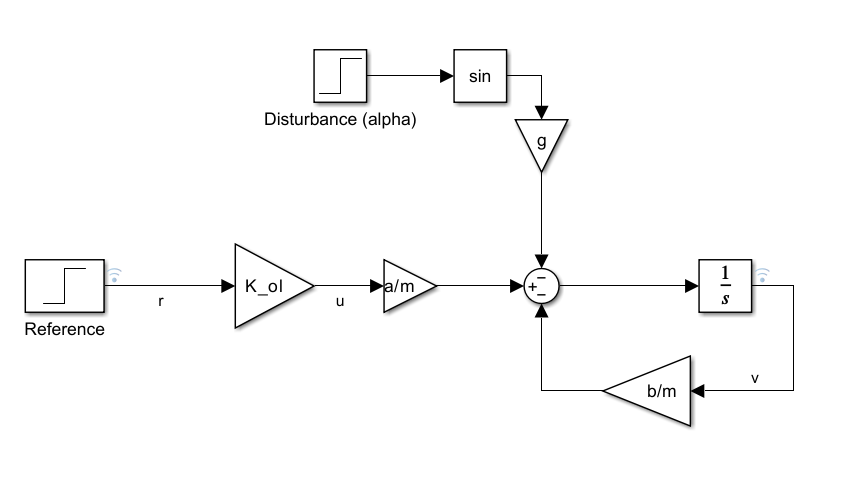

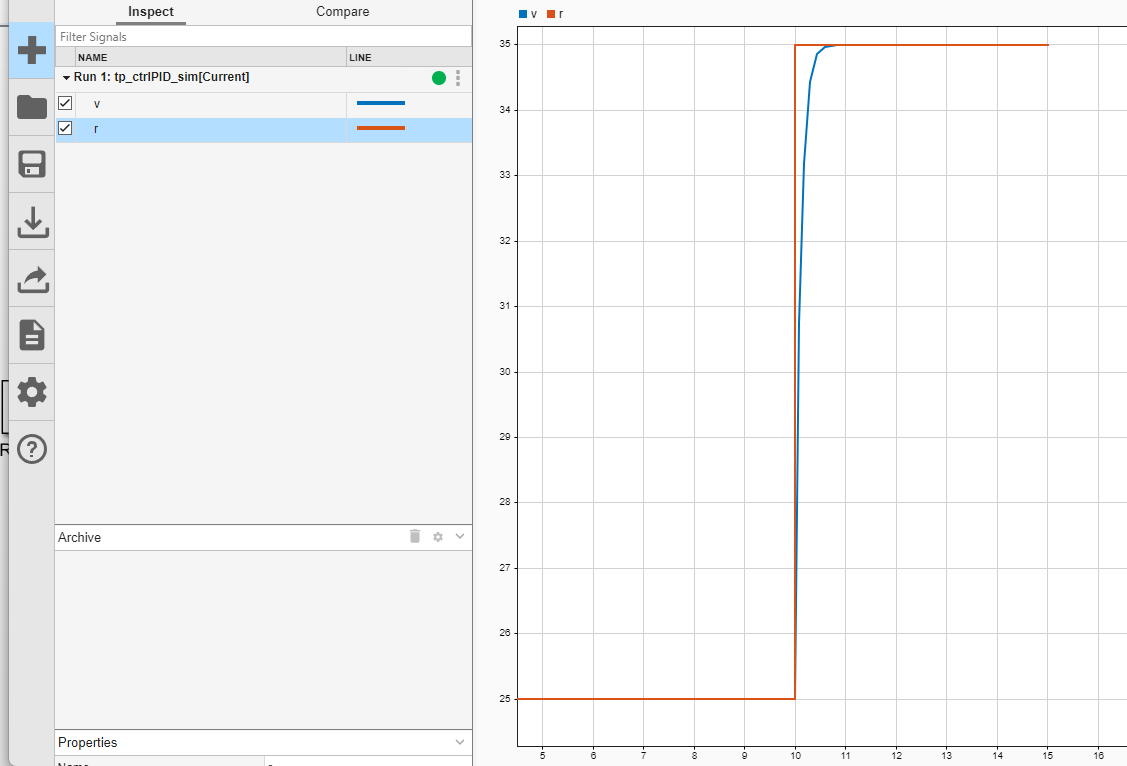

Si, es satisfactoria, ya que termina estableciendose en la velocidad requerida.

Luego aplicando la perturbación:

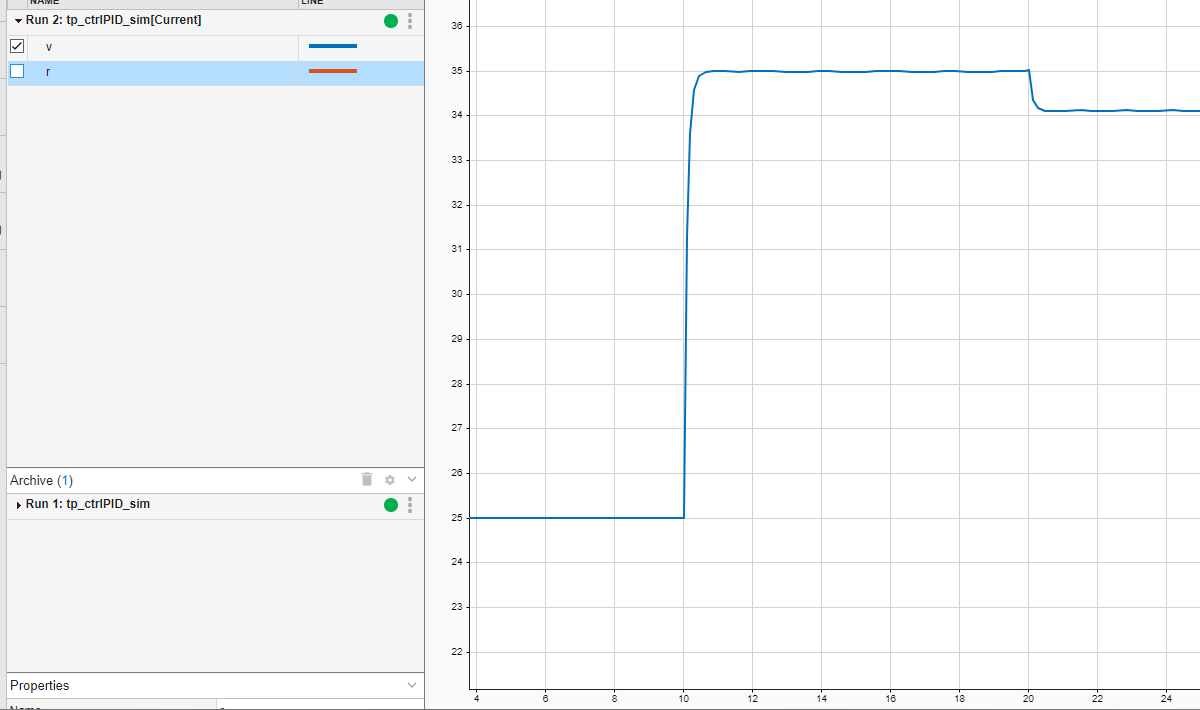

Evidentemente no es satisfactoria, dado que no hay realimentación.

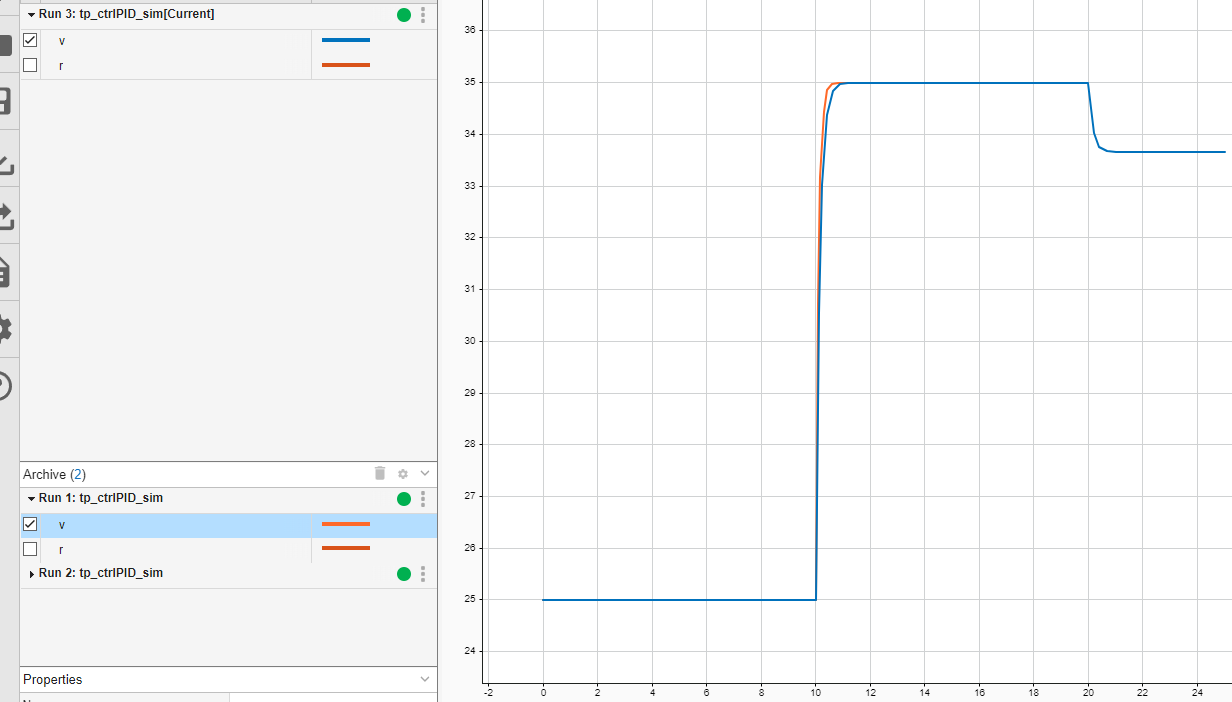

Sigue sin ser satisfactoria, solo que demora más en establecerse (azul)

#### Conclusión

Como conclusión se puede obtener que la ausencia de realimentación de la velocidad evita que el controlador pueda ajustar frente a perturbaciones que no se pueden "ver" desde la simple ley de control implementada.

### Ejercicio 2

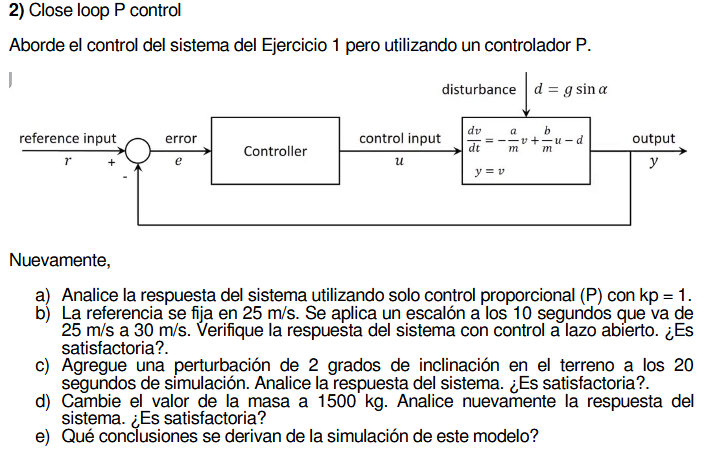

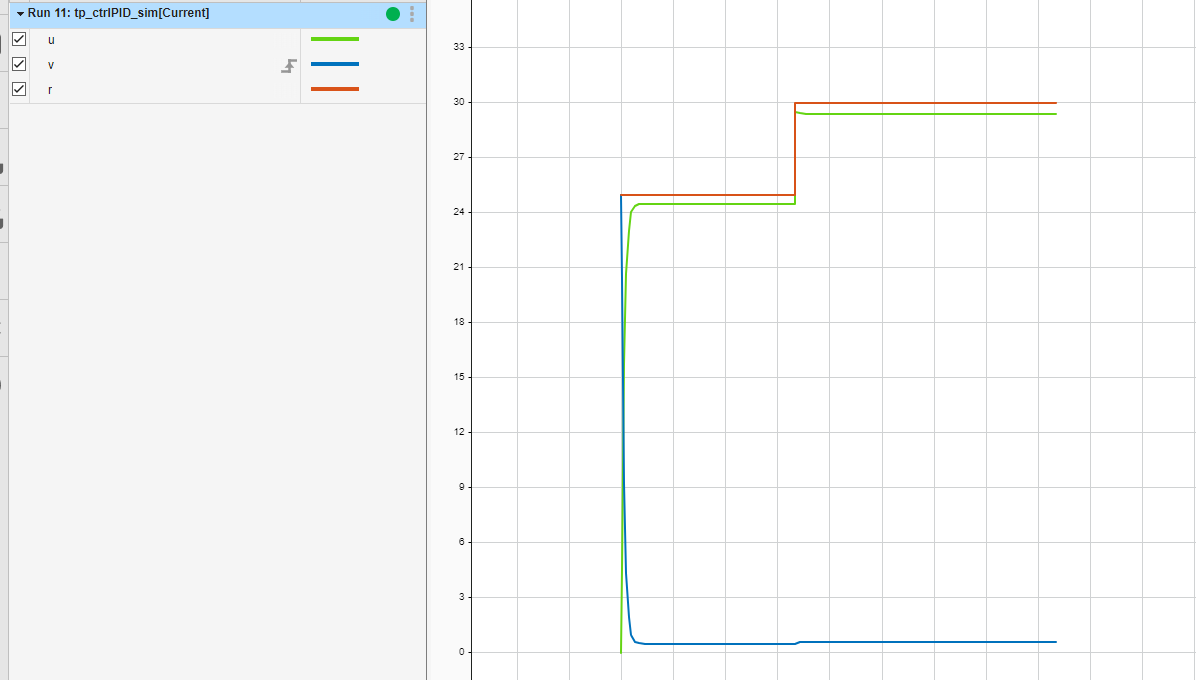

La respuesta no es satisfactoria con o sin el escalon de perturbación, esto es por la presencia de un error de estado estacionario.

### Ejercicio 3

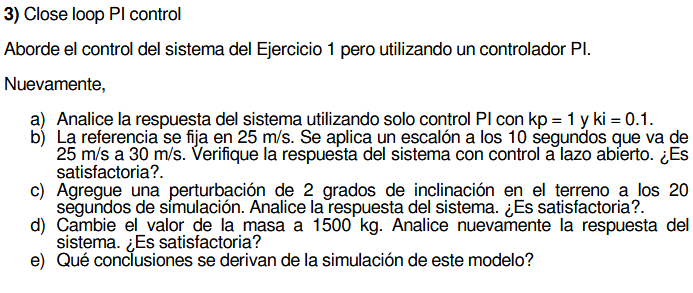

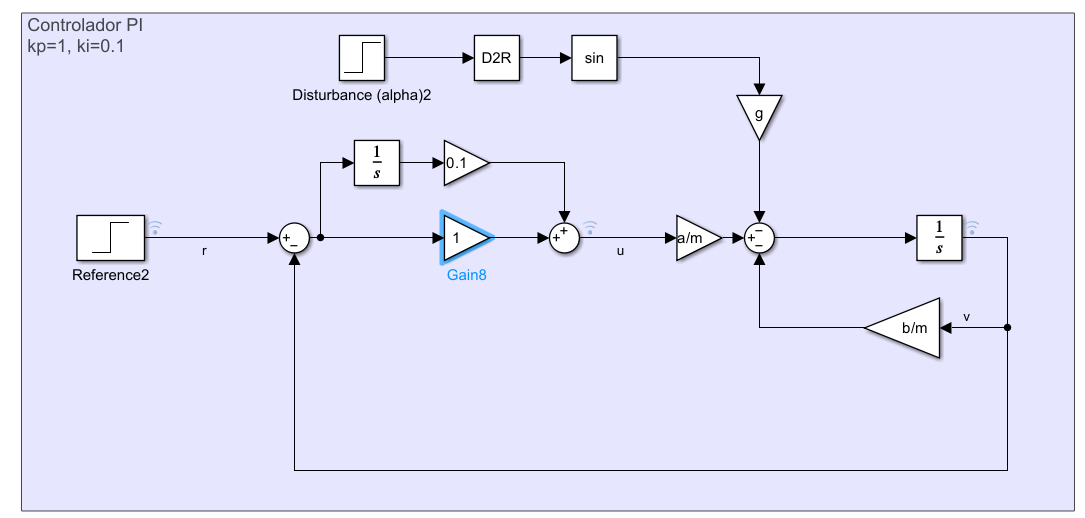

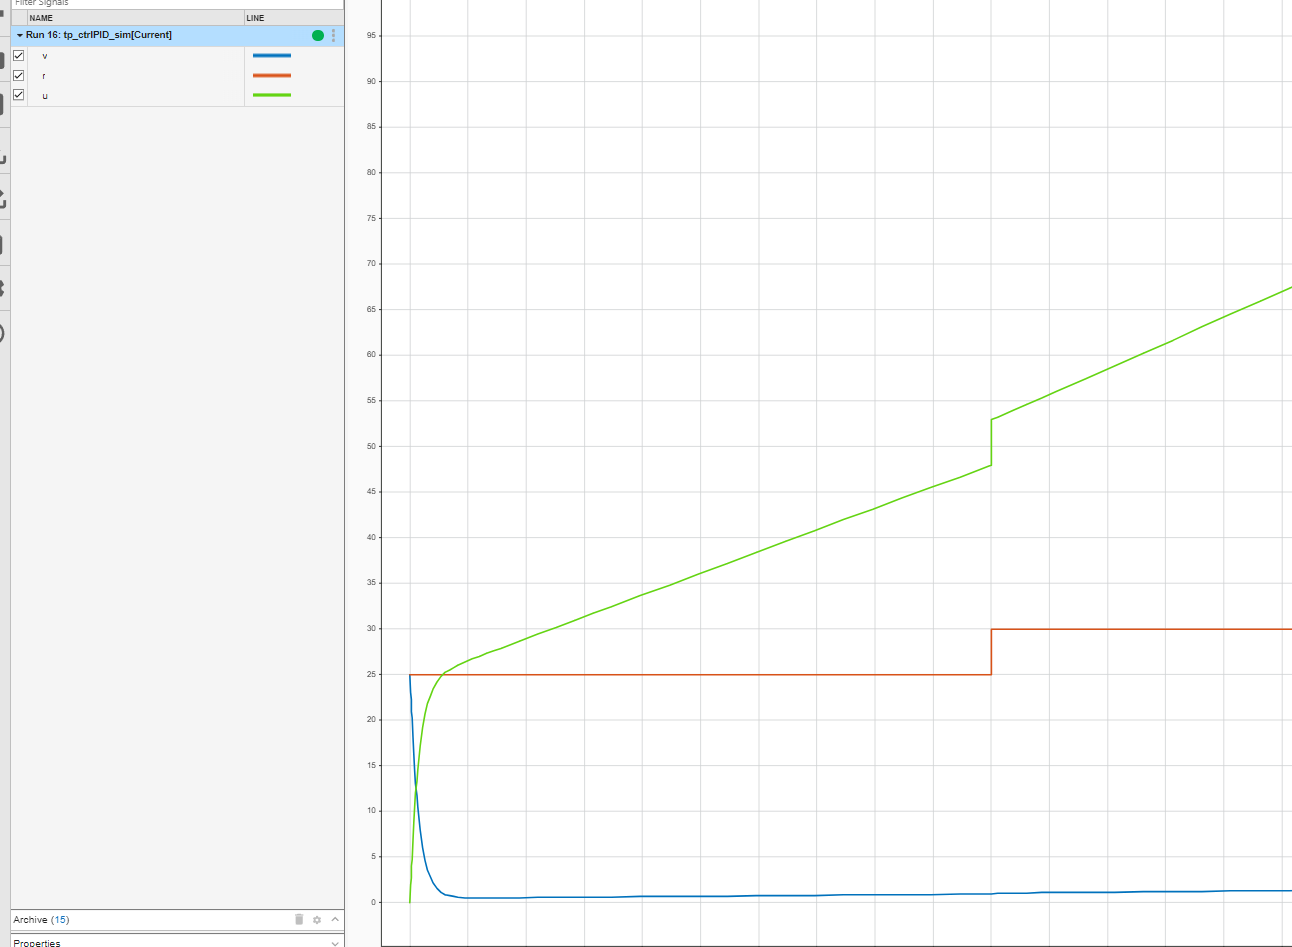

No es satisfactoria, en este caso por una mala sintonización de las ganancias.

### Ejercicio 4

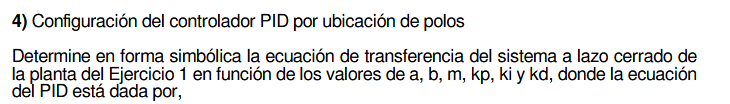

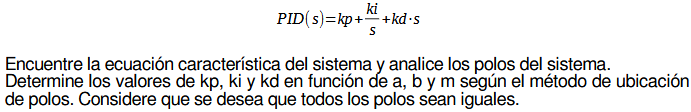

clear;
syms s beta b m kp ki kd p real


$$G(s)=\frac{Y(s)}{U(s)}=\frac{a}{ms+b}
$$


G = beta/(m*s+b);


$$PID(s) = k_p + \frac{k_i}{s}+k_ds
$$



$$C(s)=\frac{k_ps+k_i+k_ds^2}{s}$$


C = (kp*s+ki+kd*s^2)/s;


$$T(s)=\frac{Y(s)}{R(s)}=\frac{C(s)G(s)}{1+C(s)G(s)}$$


T = simplify((C*G)/(1+C*G));
disp("Transferencia en lazo cerrado: T(s)")

Transferencia en lazo cerrado: T(s)


pretty(T)

               2
        a (kd s  + kp s + ki)
------------------------------------
                2                  2
a ki + b s + m s  + a kp s + a kd s




[numT,denT]=numden(T);
denT = collect(denT,s);
coef_s2 = coeffs(denT, s, 'All');
coef_s2 = coef_s2(1);
disp("Ecuacion caracteristica: ")

Ecuacion caracteristica: 


pretty(denT == 0)

            2
(m + a kd) s  + (b + a kp) s + a ki == 0



Para el polinomio deseado


$$p_{des}=(s+p)^2
$$


pol_caracteristico_norm = simplify(denT/coef_s2);
pol_caracteristico_norm = collect(pol_caracteristico_norm,s);
disp("Ecuacion deseada: ")

Ecuacion deseada: 


p_des = s^2+2*p*s+p^2

$$p\_des = p^{2}+2\,p\,s+s^{2}$$

pretty(pol_caracteristico_norm == p_des)

 2   (b + a kp) s     a ki       2            2
s  + ------------ + -------- == p  + 2 p s + s
       m + a kd     m + a kd



Ahora igualamos coeficientes para encontrar kp, ki y kd en funcion de p

Hacemos la diferencia de los polinomios

pol_diff = expand(pol_caracteristico_norm - p_des);
pol_diff = collect(pol_diff,s);

%Igualamos coeficientes de potencias iguales
coef_diff = coeffs(pol_diff, s,'All');
eqs = coef_diff == 0;
disp("Ecuaciones al igualar coeficientes:");

Ecuaciones al igualar coeficientes:


pretty(eqs);

/     b              a kp           a ki      2      \
| -------- - 2 p + -------- == 0, -------- - p  == 0 |
\ m + a kd         m + a kd       m + a kd           /




sol = solve(eqs, [kp, ki]);
kp_sol = simplify(sol.kp)

$$kp\_sol = \frac{2\,m\,p-b+2\,a\,\mathrm{kd}\,p}{a}$$

ki_sol = simplify(sol.ki)

$$ki\_sol = \frac{p^{2}\,\left(m+a\,\mathrm{kd}\right)}{a}$$

### Ejercicio 5

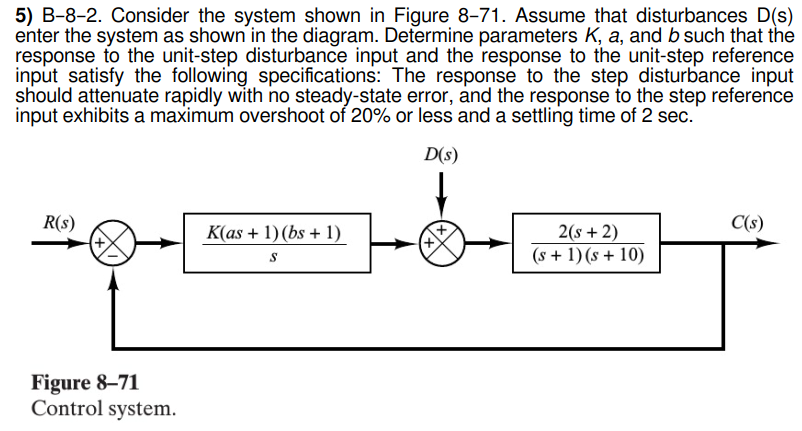

La funcion de transferencia para la perturbación se obtiene forzando R(s)=0.


$$\frac{C(s)}{D(s)}=\frac{G_p(s)}{1+G_p(s)G_c(s)}=\frac{\frac{2(s+2)}{(s+1)(s+10)}}{1+\Bigg[\frac{K(as+1)(bs+1)}{s}\cdot\frac{2(s+2)}{(s+1)(s+10)}\Bigg]}=\frac{2s(s+2)}{s(s+1)(s+10)+\big[2K(as+1)\cdot(bs+1)\cdot (s+2)\big]}$$


Expandiendo queda:


$$\frac{C(s)}{D(s)}=\frac{2s(s+2)}{s^3+11s^2+10s+2K(as+1)(bs+1)(s+2)}$$


Es decir, una respuesta de tercer orden, por lo que para aplicar criterios de diseño, es útil y necesario reducir el orden del sistema a 2, cancelando el polo mas dominante, en este caso el polo $p_1 =-1\;\frac{\textrm{rad}}{s}$

Para ello, haremos que a o b valgan 1 para que en el producto $G_c \left(s\right)G_p \left(s\right)\;$se cancele el polo.


$$a\;s+1=s+1\Rightarrow a=1$$



$$1+G_c \left(s\right)G_p \left(s\right)=0\Rightarrow G_c \left(s\right)G_p \left(s\right)=\frac{K\left(b\;s+1\right)}{s}\cdot 2\frac{\left(s+2\right)}{s+10}=2K\left(b\;s+1\right)\frac{\left(s+2\right)}{s\left(s+10\right)}$$



$$\begin{array}{l}
s\left(s+10\right)+2K\left(b\;s+1\right)\left(s+2\right)=0\\
s^2 +\left\lbrack \frac{\left(10+4K\;b+2\;K\right)}{1+2K\;b}\right\rbrack s+\left\lbrack \frac{\left(4K\right)}{1+2K\;b}\right\rbrack =0
\end{array}$$


Ahora podemos comenzar a aplicar los requerimientos de diseño.

Sobrepico Mp <= 20%

Para un sistema de segundo orden, se define el sobrepico


$$\begin{array}{l}
M_p =e^{-\;\frac{\left(\zeta \;\pi \;\right)}{\sqrt{\;1-\zeta {\;}^2 }}} \le 0\ldotp 20\\
-\;\frac{\left(\zeta \;\pi \;\right)}{\sqrt{\;1-\zeta {\;}^2 }}\le \ln \left(0\ldotp 20\right)\\
\zeta {\;}^2 \frac{\pi^2 }{1-\zeta^2 }\ge {\ln \left(0\ldotp 2\right)}^2 \\
\zeta^2 \pi^2 \ge \left(1-\zeta^2 \right){\ln \left(0\ldotp 2\right)}^2 \\
\left(\pi^2 +{\ln \left(0\ldotp 2\right)}^2 \right)\zeta^2 \ge {\ln \left(0\ldotp 2\right)}^2 \\
\zeta^2 \ge \frac{\;{\ln \left(0\ldotp 2\right)}^2 }{\pi^2 +{\ln \left(0\ldotp 2\right)}^2 }
\end{array}$$


Como $0<\zeta <1$ la unica solucion que queda es $\zeta \ge 0\ldotp 4559\;$

Por lo tanto podemos elegir tranquilamente $\zeta =0\ldotp 5$

Luego para el tiempo de establecimiento aplicando el criterio del 2% tenemos


$$t_s =\frac{4}{\zeta \;\omega_n }\Rightarrow \frac{4}{0\ldotp 5}\;\frac{1}{2\;}\;\frac{1}{\textrm{seg}}=\omega_n \Rightarrow 4\;\frac{\textrm{rad}}{\textrm{seg}}$$


Podemos finalmente armar el polinomio deseado


$$s^2 +2\omega_n \zeta s+\omega_n^2 =0\Rightarrow s^2 +4s+16=0$$


Igualando coeficientes de igual orden


$$\frac{\left(4K\right)}{1+2K\;b}=16\Rightarrow 4K=16+32\textrm{Kb}\Rightarrow \left(4-32b\right)K=16\Rightarrow K=\frac{16}{4-32b}$$



$$\begin{array}{l}
\frac{\left(10+4K\;b+2\;K\right)}{1+2K\;b}=4\\
10+4\cdot \frac{16}{4-32\;b}b+2\;\frac{16}{4-32\;b}=4+8\;\frac{16}{4-32b}b\\
10+\frac{64\;b+32}{4-32\;b}=4+\frac{128\;b}{4-32\;b}\\
40-320b+64b+32=16-128b+128\;b\\
-256\;b+72=16\\
-256\;b=-56\\
b=0\ldotp 2188\Rightarrow K=-5\ldotp 33
\end{array}$$
 

Usar el método del lugar de las raices de forma analítica produjo un resultado que solo es posible de resolver con sobreamortiguamiento, por lo que perdería sentido el criterio de diseño de maximo sobrepico de 20%, ya que este no existe en un sistema sobreamortiguado.

Por lo que se propone otra vía:

Reduciremos un orden al controlador, logrando que la función de transferencia sea un polinomio propio, reducimos el controlador PID a un controlador PI con un solo cero.


$$G_{\textrm{PI}} \left(s\right)=\frac{\;K\left(b\;s+1\right)}{s}$$
 

Luego hacemos $b=0\ldotp 5$ para igualar los ceros con el cero de la planta

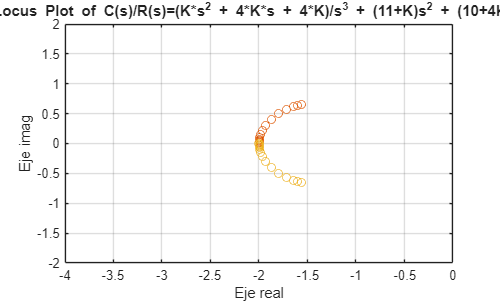

% Script de MATLAB: Simulación del Sistema B-8-2 (Referencia y Perturbación)
clear; clc; close all;

% 1. Definición de la ganancia de diseño 
K = 20; 

% 2. Construcción de los polinomios de lazo cerrado (a = 0, b = 0.5)
% Denominador común: s^3 + (11+K)s^2 + (10+4K)s + 4K
den = [1, (11 + K), (10 + 4*K), 4*K];

% Numerador de la Referencia: K*s^2 + 4*K*s + 4*K
num_ref = [K, 4*K, 4*K];
r = rlocus(num_ref,den);
plot(r,'o')
v =[-4 0 -2 2]; axis(v);
grid
title('Root-Locus Plot of C(s)/R(s)=(K*s^2 + 4*K*s + 4*K)/s^3 + (11+K)s^2 + (10+4K)s + 4K')
xlabel('Eje real')
ylabel('Eje imag')

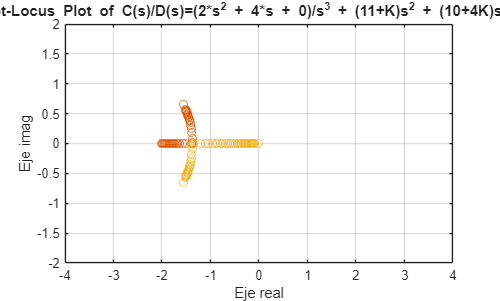


% Numerador de la Perturbación: 2*s^2 + 4*s + 0
num_dist = [2, 4, 0];
r = rlocus(num_dist,den);
plot(r,'o')
v =[-4 4 -2 2]; axis(v);
grid
title('Root-Locus Plot of C(s)/D(s)=(2*s^2 + 4*s + 0)/s^3 + (11+K)s^2 + (10+4K)s + 4K')
xlabel('Eje real')
ylabel('Eje imag')

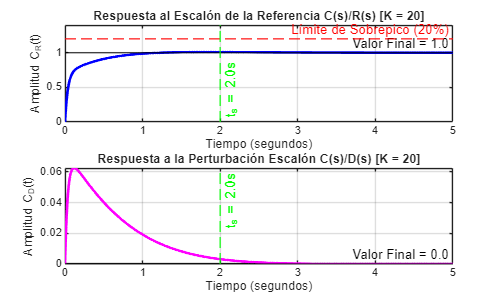

% Crear las funciones de transferencia
sys_referencia = tf(num_ref, den);
sys_perturbacion = tf(num_dist, den);

% 3. Vector de tiempo común para la simulación
t = 0:0.005:5;

% 4. Ejecución de la simulación temporal ante entrada escalón unitario
[y_ref, t_ref] = step(sys_referencia, t);
[y_dist, t_dist] = step(sys_perturbacion, t);

% =========================================================================
% GRAFICACIÓN DE LOS RESULTADOS
% =========================================================================
figure('Name', ['Simulación del Sistema de Control con K = ' num2str(K)], 'NumberTitle', 'off');

% --- SUBPLOT 1: RESPUESTA A LA REFERENCIA ---
subplot(2, 1, 1);
plot(t_ref, y_ref, 'b', 'LineWidth', 2);
hold on; grid on;

% Líneas de referencia para diseño
yline(1, 'k-', 'Valor Final = 1.0', 'LineWidth', 1);
yline(1.20, 'r--', 'Límite de Sobrepico (20%)', 'LineWidth', 1.2);
xline(2, 'g--', 't_s = 2.0s', 'LineWidth', 1.2, 'LabelVerticalAlignment', 'bottom');

title(['Respuesta al Escalón de la Referencia C(s)/R(s) [K = ' num2str(K) ']']);
xlabel('Tiempo (segundos)');
ylabel('Amplitud C_R(t)');
xlim([0 5]);
ylim([0 1.4]);

% --- SUBPLOT 2: RESPUESTA A LA PERTURBACIÓN ---
subplot(2, 1, 2);
plot(t_dist, y_dist, 'm', 'LineWidth', 2);
hold on; grid on;

% Líneas de referencia para diseño
yline(0, 'k-', 'Valor Final = 0.0', 'LineWidth', 1);
xline(2, 'g--', 't_s = 2.0s', 'LineWidth', 1.2, 'LabelVerticalAlignment', 'top');

% Calcular y mostrar el porcentaje del pico remanente a los 2 segundos
peak_dist = max(abs(y_dist));
idx_2s = find(t_dist >= 2, 1);
val_2s = y_dist(idx_2s);
pct_remanente = (val_2s / peak_dist) * 100;

title(['Respuesta a la Perturbación Escalón C(s)/D(s) [K = ' num2str(K) ']']);
xlabel('Tiempo (segundos)');
ylabel('Amplitud C_D(t)');
xlim([0 5]);


% 5. Despliegue de métricas numéricas exactas en la ventana de comandos
fprintf('==================================================\n');

fprintf('  MÉTRICAS DEL SISTEMA EN LAZO CERRADO CON K = %d\n', K);

  MÉTRICAS DEL SISTEMA EN LAZO CERRADO CON K = 20


fprintf('==================================================\n');

info_ref = stepinfo(sys_referencia);
fprintf('REFERENCIA R(s):\n');

REFERENCIA R(s):


fprintf(' -> Sobrepico (Overshoot): %.2f %%\n', info_ref.Overshoot);

 -> Sobrepico (Overshoot): 0.92 %


fprintf(' -> Tiempo de asentamiento (2%%): %.4f s\n\n', info_ref.SettlingTime);

 -> Tiempo de asentamiento (2%): 0.9263 s




fprintf('PERTURBACIÓN D(s):\n');

PERTURBACIÓN D(s):


fprintf(' -> Valor máximo del desvío (Pico): %.4f\n', peak_dist);

 -> Valor máximo del desvío (Pico): 0.0625


fprintf(' -> Valor remanente a los 2.0 segundos: %.6f\n', val_2s);

 -> Valor remanente a los 2.0 segundos: 0.003087


fprintf(' -> Porcentaje del pico original a los 2.0s: %.2f %%\n', pct_remanente);

 -> Porcentaje del pico original a los 2.0s: 4.94 %


fprintf('==================================================\n');

Experimentalmente puede verse que a partir de K=20 el remanente del pico original de la perturbacion en t=2 s es menor al 5%, por lo que es aceptable para decir que esta lo suficientemente asentado.

### Ejercicio 6

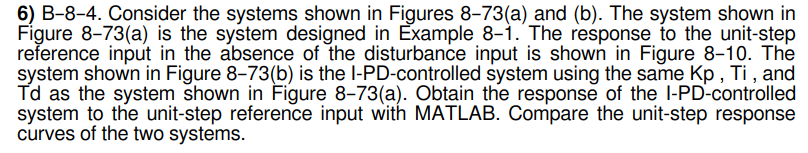

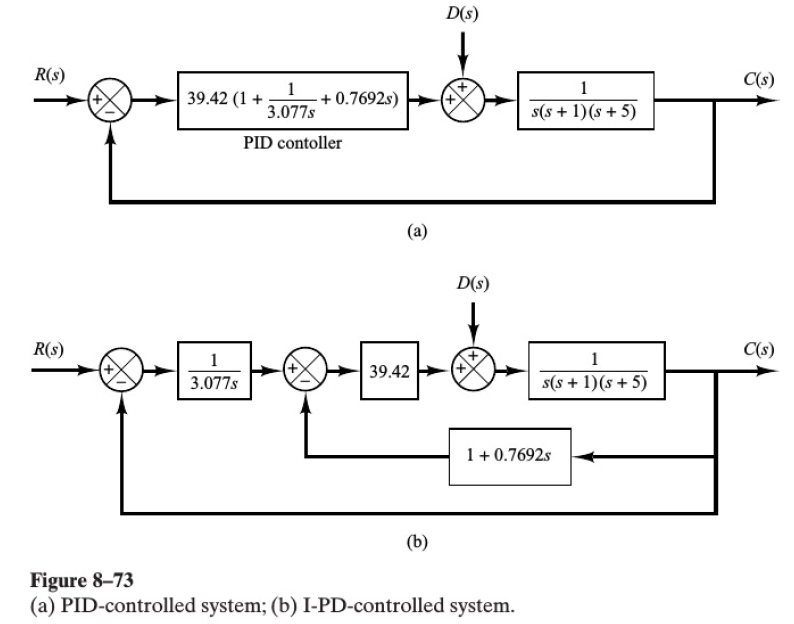

Primero grafiquemos la respuesta al escalon unitario del sistema de PID

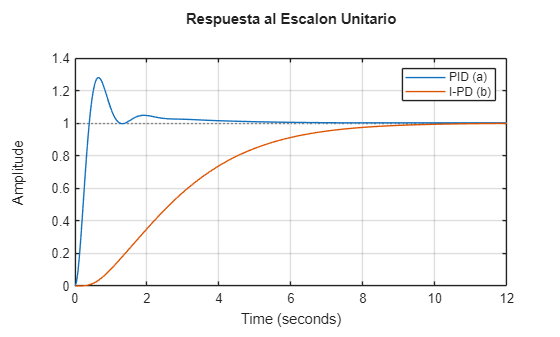

s = tf('s');

G_p = 1/(s*(s+1)*(s+5));
G_c_PID = 39.42*(1+1/(3.077*s)+0.7692*s);
lazo_interno_D = feedback(39.42*G_p, 1+0.7692*s);
sys_b = feedback((1/(3.077*s))*lazo_interno_D, 1);
sys_a = feedback(G_p*G_c_PID, 1);
figure;
step(sys_a,sys_b);
legend('PID (a)','I-PD (b)');
title('Respuesta al Escalon Unitario');
grid on;

### Ejercicio 7

s = tf('s');
G_p = 1/(s*(s+1)*(s+5));
G_c_PID = 39.42*(1+1/(3.077*s)+0.7692*s);

%camino directo
sys_a_D = feedback(G_p, G_c_PID);

H_b = 39.42*(1/(3.077*s)+1+0.7692*s);
sys_b_D = feedback(G_p, H_b);
disp('Función de transferencia C(s)/D(s) para PID (Sistema a):');

Función de transferencia C(s)/D(s) para PID (Sistema a):


sys_a_D


sys_a_D =
 
                        3.077 s
  ---------------------------------------------------
  3.077 s^4 + 18.46 s^3 + 108.7 s^2 + 121.3 s + 39.42
 
Continuous-time transfer function.


disp('Función de transferencia C(s)/D(s) para I-PD (Sistema b):');

Función de transferencia C(s)/D(s) para I-PD (Sistema b):


sys_b_D


sys_b_D =
 
                        3.077 s
  ---------------------------------------------------
  3.077 s^4 + 18.46 s^3 + 108.7 s^2 + 121.3 s + 39.42
 
Continuous-time transfer function.


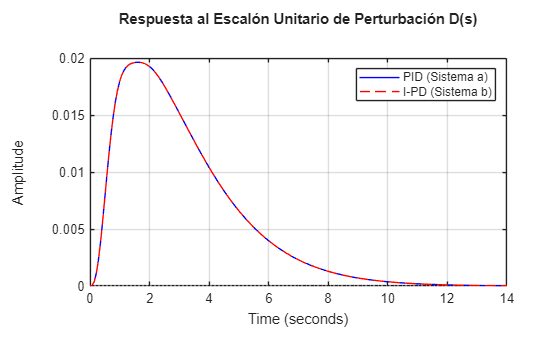

figure;
% Se grafica el sistema 'a' en línea azul gruesa continua y el 'b' en roja punteada
step(sys_a_D, 'b-', sys_b_D, 'r--'); 
legend('PID (Sistema a)', 'I-PD (Sistema b)');
title('Respuesta al Escalón Unitario de Perturbación D(s)');
grid on;

### Ejercicio 8

clear;
s = tf('s');
G_p = 2*(s+1)/(s*(s+3)*(s+5));


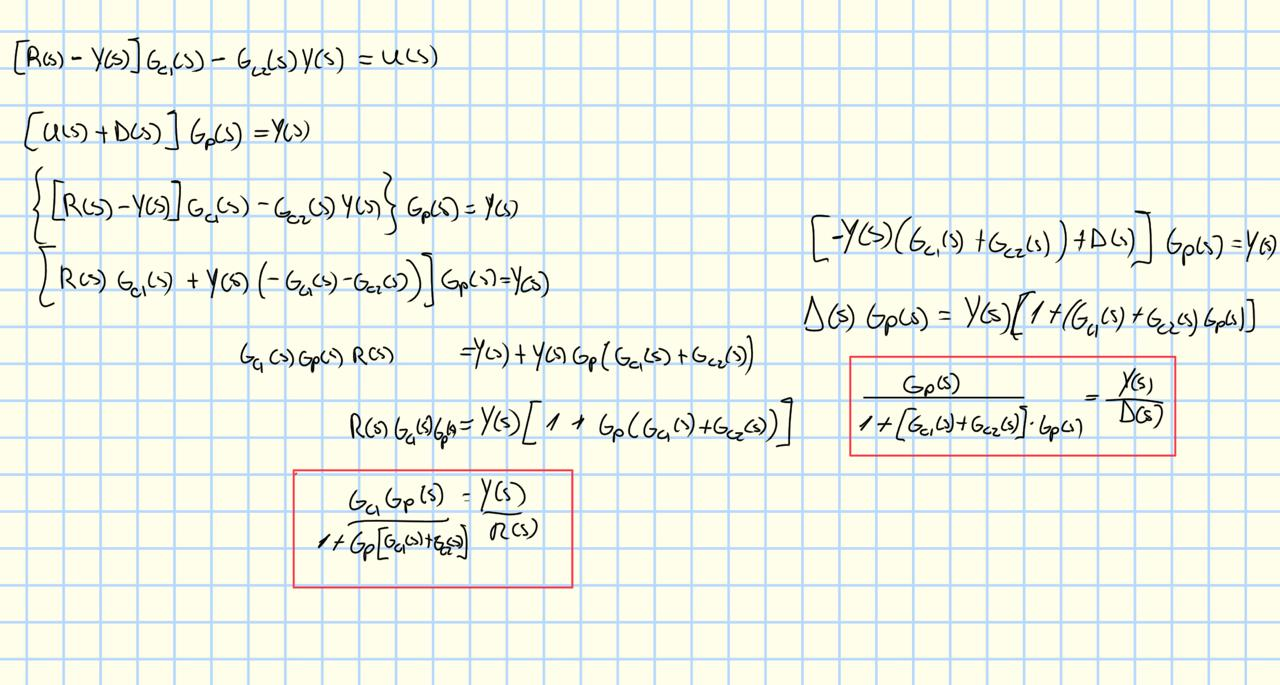

Definimos como funciones de transferencia deseadas:


$$\frac{Y\left(s\right)}{D\left(s\right)}=M\left(s\right);\frac{Y\left(s\right)}{R\left(s\right)}=H\left(s\right)$$


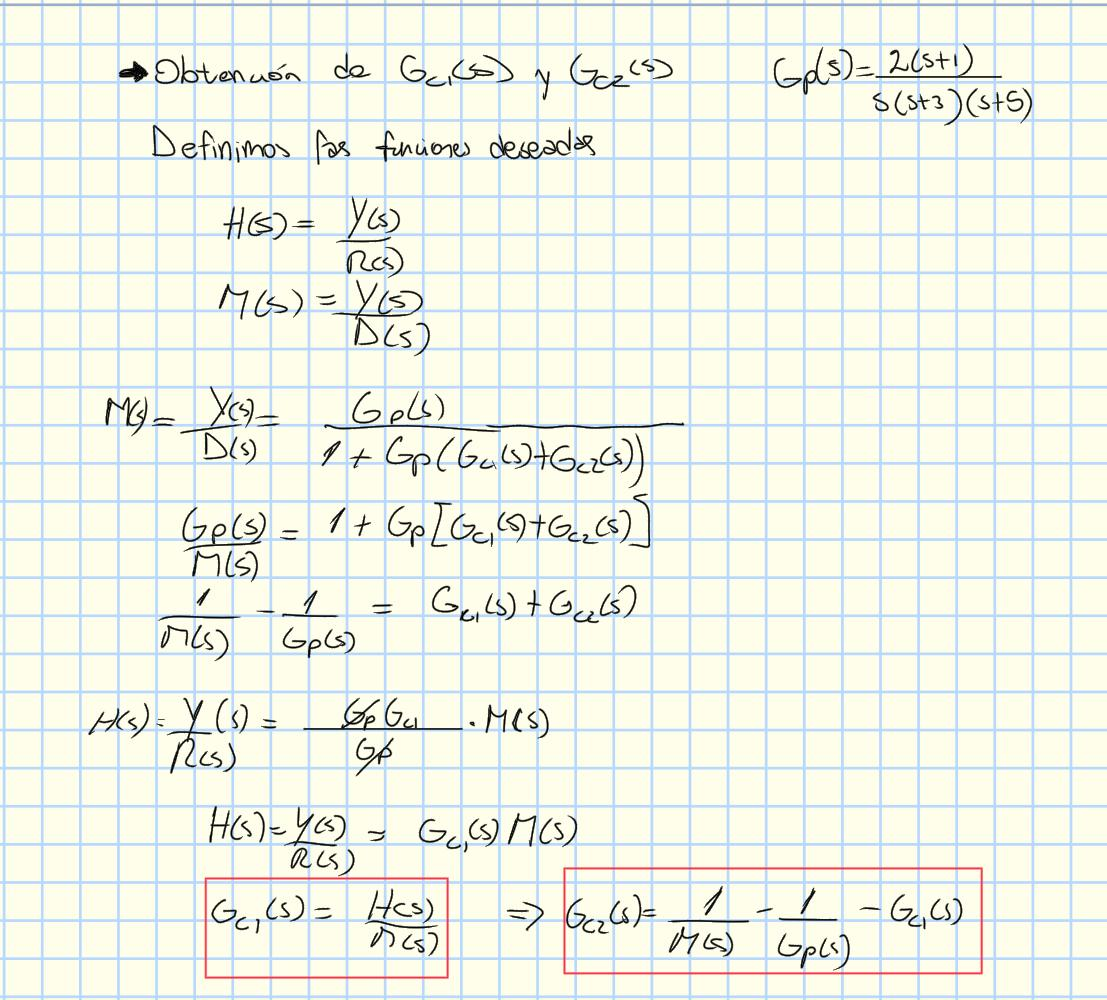

Luego de proponer a $M\left(s\right)=\frac{\;s}{{\left(s+a\right)}^2 }$

Iteramos sobre **a** para cumplir la condicion de diseño para entrada escalon de perturbación, teniendo en cuenta que en el tiempo $y\left(t\right)=t\;e^{-a\;t}$ , $y_{\max } =\frac{1}{a\;e}$    y la condicion de diseño seria $y\left(T\right)\le 0\ldotp 05\;y_{\max }$ donde **T **es el settling time que se elija.

T = 1;
p = 0.05;

for beta = 0.01 : 0.0001 : 50
    tmax = 1/beta;

    if T >= tmax
        ratio = beta*T*exp(1 - beta*T);

        if ratio <= p
            fprintf('a_min = %.4f\n', beta);
            fprintf('ratio = %.4f\n', ratio);
            break
        end
    end
end

a_min = 5.7439


ratio = 0.0500


Dado que el a minimo dió $\approx 5\ldotp 74$ elegimos $a=6$ 

Luego, dado que se desea error de estado estacionario nulo hasta para una referencia parábola.

$1-H\left(s\right)\;$tendría que tener al menos $s^3$como factor y ser propia.


$$1-H\left(s\right)=\frac{s^3 }{\textrm{denominador}\;\textrm{estable}}$$



$$1-H\left(s\right)=\frac{s^3 }{Q\left(s\right)}$$


Elegimos a $Q\left(s\right)\;$arbitrariamente estable de la forma:  $Q\left(s\right)={\left(s+\beta \right)}^2 \left(s+k\beta \right)\;;k=1,2,3\;\ldotp \ldotp \ldotp$

Podemos plantear un pequeño código para iterar sobre valores de $\beta$ dejando $k\;$ fijo.

clear; clc;

Ts_max = 1;
OS_max = 20;

k = 2;
beta_values = 0.1:0.01:50;

s = tf('s');

found = false;

for beta = beta_values

    Q = (s+beta)^2*(s+k*beta);
    H = 1 - s^3/Q;

    info = stepinfo(H); %usamos la funcion stepinfo para obtener la información experimental

    Ts = info.SettlingTime; 
    OS = info.Overshoot;

    if Ts <= Ts_max && OS <= OS_max
        found = true;

        fprintf('Valor encontrado:\n');
        fprintf('beta = %.4f\n', beta);
        fprintf('k = %.4f\n', k);
        fprintf('Settling time = %.4f s\n', Ts);
        fprintf('Overshoot = %.4f %%\n', OS);

        figure;
        step(H);
        grid on;
        title(sprintf('Respuesta al escalón: beta = %.4f, k = %.2f', beta, k));

        break
    end
end

Valor encontrado:


beta = 2.4200


k = 2.0000


Settling time = 0.9999 s


Overshoot = 19.4717 %



if ~found
    fprintf('No se encontró un valor de a en el rango probado.\n');
end

Obtenemos que para k=2, un  beta que cumpliria la performance pedida seria $\beta =2\ldotp 42$, este valor nos sirve como una buena primera aproximación, simplemente para mejorar el overshoot, deberiamos correr el polo mas rápido a la izquierda, aumentando el valor de k, para esto tambien adoptaremos $\beta =4$ para cumplir con la performance en tiempo (settling time).

clear; clc; close all;

% Valores a probar
beta = 4;
k = 8;

s = tf('s');

% Q(s) = (s+a)^2(s+k*a)
Q = (s+beta)^2*(s+k*beta);

% H(s) = 1 - s^3/Q(s)
H = 1 - s^3/Q;

% Mostrar transferencias
disp('Q(s) = ')

Q(s) = 


Q


Q =
 
  s^3 + 40 s^2 + 272 s + 512
 
Continuous-time transfer function.



disp('H(s) = ')

H(s) = 


H


H =
 
     40 s^2 + 272 s + 512
  --------------------------
  s^3 + 40 s^2 + 272 s + 512
 
Continuous-time transfer function.



% Respuesta al escalón
info = stepinfo(H);

fprintf('Overshoot = %.4f %%\n', info.Overshoot);

Overshoot = 11.8832 %


fprintf('Settling time = %.4f s\n', info.SettlingTime);

Settling time = 0.3774 s


fprintf('Rise time = %.4f s\n', info.RiseTime);

Rise time = 0.0397 s


fprintf('Peak time = %.4f s\n', info.PeakTime);

Peak time = 0.1151 s


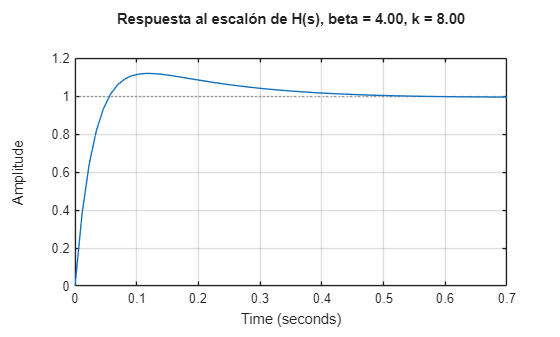


% Gráfico
figure;
step(H);
grid on;
title(sprintf('Respuesta al escalón de H(s), beta = %.2f, k = %.2f', beta, k));

Teniamos


$$G_{\textrm{c1}} \left(s\right)=\frac{H\left(s\right)}{M\left(s\right)\;}\;;G_{\textrm{c2}} \left(s\right)=\frac{1}{M\left(s\right)\;}-\frac{1}{G_p \left(s\right)}-G_{\textrm{c1}} \left(s\right)$$



$$G_{\textrm{c1}} \left(s\right)=\frac{40\;s^{\;2} +272\;s+512}{{\left(s+4\right)}^2 \left(s+8\cdot 4\right)}$$



$$G_{\textrm{c2}} \left(s\right)=\frac{{\left(s+6\right)}^2 }{s}-\frac{s\left(s+3\right)\left(s+5\right)}{2\left(s+1\right)}-\frac{40\;s^{\;2} +272\;s+512}{{\left(s+4\right)}^2 \left(s+32\right)}$$


s = tf('s');

Gc2 = (s+6)^2/s ...
    - s*(s+3)*(s+5)/(2*(s+1)) ...
    - (40*s^2 + 272*s + 512)/((s+4)^2*(s+32));

Gc2 = minreal(Gc2);

tf(Gc2)


ans =
 
  -0.5 s^7 - 23 s^6 - 250.5 s^5 - 844 s^4 + 1604 s^3 + 1.653e04 s^2 + 3.386e04 s + 1.843e04
  -----------------------------------------------------------------------------------------
                          s^5 + 41 s^4 + 312 s^3 + 784 s^2 + 512 s
 
Continuous-time transfer function.


zpk(Gc2)


ans =
 
  -0.5 (s+32.1) (s-3.868) (s+0.8761) (s^2 + 6.973s + 12.57) (s^2 + 9.922s + 26.96)
  --------------------------------------------------------------------------------
                               s (s+32) (s+4)^2 (s+1)
 
Continuous-time zero/pole/gain model.


Finalmente para comprobar el diseño

clear; clc; close all;

s = tf('s');

%% Planta
Gp = 2*(s+1)/(s*(s+3)*(s+5));

%% M(s): perturbacion -> salida
% M(s) = s/(s+b)^2
b = 6;
M = s/(s+b)^2;

%% H(s): referencia -> salida
% 1 - H(s) = s^3/Q(s)
% Q(s) = (s+a)^2(s+k*a)

beta = 4;
k = 8;

Q = (s+beta)^2*(s+k*beta);
H = minreal(1 - s^3/Q);

%% Controladores
Gc1 = minreal(H/M);
Gc2 = minreal(1/M - 1/Gp - Gc1);

disp('Gc1(s) = ')

Gc1(s) = 


Gc1


Gc1 =
 
  40 s^4 + 752 s^3 + 5216 s^2 + 1.594e04 s + 18432
  ------------------------------------------------
           s^4 + 40 s^3 + 272 s^2 + 512 s
 
Continuous-time transfer function.



disp('Gc2(s) = ')

Gc2(s) = 


Gc2


Gc2 =
 
  -0.5 s^7 - 23 s^6 - 290.5 s^5 - 1596 s^4 - 4052 s^3 - 3840 s^2 - 2.183e-11 s - 1.455e-11
  ----------------------------------------------------------------------------------------
                          s^5 + 41 s^4 + 312 s^3 + 784 s^2 + 512 s
 
Continuous-time transfer function.



%% Transferencias reales del sistema completo
YR = minreal(Gp*Gc1 / (1 + Gp*(Gc1 + Gc2)));
YD = minreal(Gp     / (1 + Gp*(Gc1 + Gc2)));

disp('Chequeo Y/R - H:')

Chequeo Y/R - H:


minreal(YR - H)


ans =
 
                  -1.039e-06 s^15 - 0.0001483 s^14 - 0.008887 s^13 - 0.2953 s^12 - 6.121 s^11 - 85.08 s^10 - 831.1 s^9 - 5873 s^8 - 3.05e04 s^7 - 1.17e05 s^6 - 3.293e05 s^5 - 6.679e05 s^4 - 9.424e05 s^3 - 8.681e05 s^2 - 4.63e05 s - 1.071e05
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^17 + 179 s^16 + 1.386e04 s^15 + 6.13e05 s^14 + 1.732e07 s^13 + 3.328e08 s^12 + 4.539e09 s^11 + 4.531e10 s^10 + 3.378e11 s^9 + 1.904e12 s^8 + 8.143e12 s^7 + 2.637e13 s^6 + 6.395e13 s^5 + 1.136e14 s^4 + 1.423e14 s^3 + 1.181e14 s^2 + 5.762e13 s + 1.237e13
 
Continuous-time transfer function.



disp('Chequeo Y/D - M:')

Chequeo Y/D - M:


minreal(YD - M)


ans =
 
             4.205e-09 s^10 + 3.74e-07 s^9 + 1.209e-05 s^8 + 0.0001818 s^7 + 0.001484 s^6 + 0.007046 s^5 + 0.01969 s^4 + 0.03115 s^3 + 0.02501 s^2 + 0.007812 s
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 106 s^11 + 4489 s^10 + 1.01e05 s^9 + 1.384e06 s^8 + 1.24e07 s^7 + 7.526e07 s^6 + 3.137e08 s^5 + 8.911e08 s^4 + 1.675e09 s^3 + 1.961e09 s^2 + 1.267e09 s + 3.397e08
 
Continuous-time transfer function.


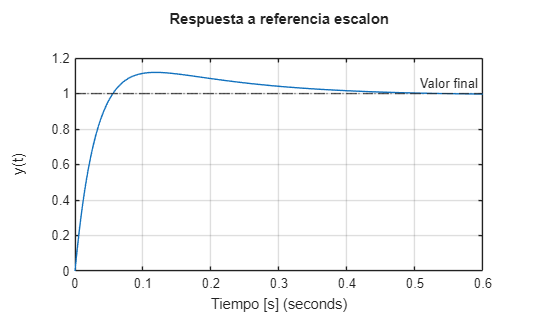


%% ============================================================
%  1) Respuesta a referencia escalon
% ============================================================

figure;
step(YR);
grid on;
hold on;

yline(1, '--', 'Valor final');
yline(1.2, '--', '20% overshoot');

title('Respuesta a referencia escalon');
xlabel('Tiempo [s]');
ylabel('y(t)');


info_R = stepinfo(YR);

fprintf('\nReferencia escalon:\n');


Referencia escalon:


fprintf('Overshoot = %.4f %%\n', info_R.Overshoot);

Overshoot = 11.8957 %


fprintf('Settling time = %.4f s\n', info_R.SettlingTime);

Settling time = 0.3773 s


fprintf('Rise time = %.4f s\n', info_R.RiseTime);

Rise time = 0.0396 s


fprintf('Peak time = %.4f s\n', info_R.PeakTime);

Peak time = 0.1180 s



%% ============================================================
%  2) Respuesta a perturbacion escalon
% ============================================================

tD = linspace(0, 3, 2000);
[yD, tD] = step(YD, tD);

yD_peak = max(yD);
criterion_5 = 0.05*yD_peak;

figure;
plot(tD, yD, 'LineWidth', 1.5);
grid on;
hold on;

yline(yD_peak, '--', 'Pico');
yline(criterion_5, '--', '5% del pico');
yline(0, '--', 'Cero');

title('Respuesta a perturbacion escalon');
xlabel('Tiempo [s]');
ylabel('y_D(t)');

fprintf('\nPerturbacion escalon:\n');


Perturbacion escalon:


fprintf('Peak = %.6f\n', yD_peak);

Peak = 0.061313


fprintf('5%% del pico = %.6f\n', criterion_5);

5% del pico = 0.003066


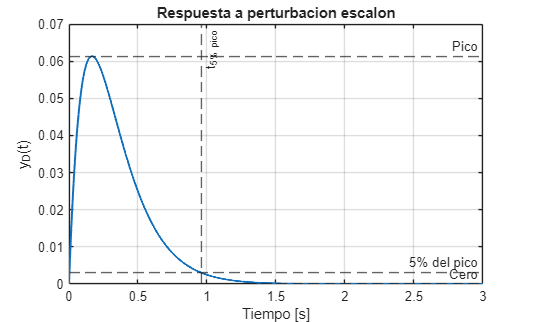

Tiempo para quedar debajo del 5% del pico = 0.9575 s



% Tiempo a partir del cual queda por debajo del 5% del pico
idx_peak = find(yD == yD_peak, 1, 'first');

idx_settle_5 = [];
for i = idx_peak:length(tD)
    if all(abs(yD(i:end)) <= criterion_5)
        idx_settle_5 = i;
        break
    end
end

if ~isempty(idx_settle_5)
    fprintf('Tiempo para quedar debajo del 5%% del pico = %.4f s\n', tD(idx_settle_5));
    xline(tD(idx_settle_5), '--', 't_{5% pico}');
else
    fprintf('No queda debajo del 5%% del pico en el intervalo simulado.\n');
end

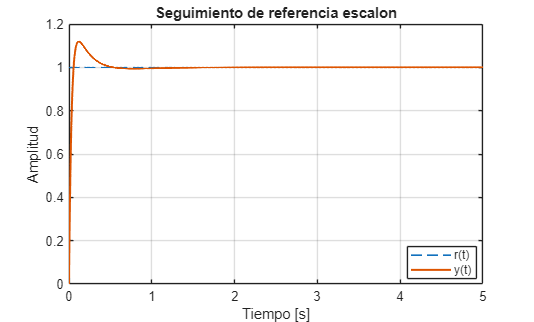


%% ============================================================
%  3) Referencia escalon, rampa y aceleracion
% ============================================================

t = linspace(0, 5, 3000);

r_step = ones(size(t));
r_ramp = t;
r_acc  = 0.5*t.^2;   % aceleracion unitaria: r(t)=t^2/2

y_step = lsim(YR, r_step, t);
y_ramp = lsim(YR, r_ramp, t);
y_acc  = lsim(YR, r_acc,  t);

e_step = r_step(:) - y_step;
e_ramp = r_ramp(:) - y_ramp;
e_acc  = r_acc(:)  - y_acc;

figure;
plot(t, r_step, '--', 'LineWidth', 1.2); hold on;
plot(t, y_step, 'LineWidth', 1.5);
grid on;
title('Seguimiento de referencia escalon');
xlabel('Tiempo [s]');
ylabel('Amplitud');
legend('r(t)', 'y(t)', 'Location', 'best');

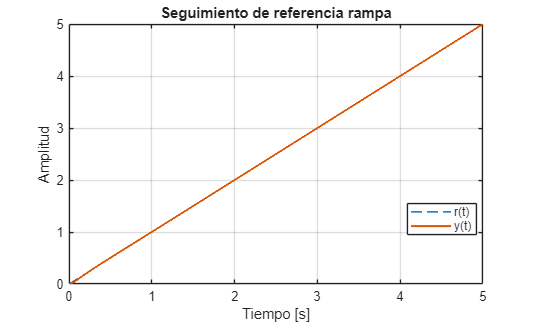


figure;
plot(t, r_ramp, '--', 'LineWidth', 1.2); hold on;
plot(t, y_ramp, 'LineWidth', 1.5);
grid on;
title('Seguimiento de referencia rampa');
xlabel('Tiempo [s]');
ylabel('Amplitud');
legend('r(t)', 'y(t)', 'Location', 'best');

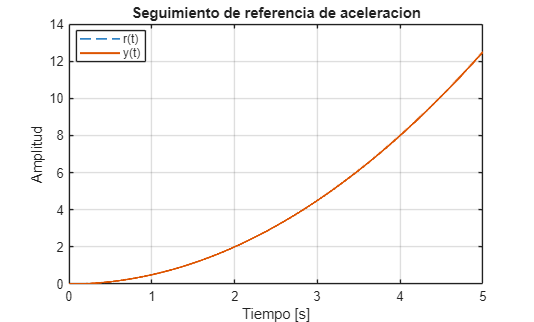


figure;
plot(t, r_acc, '--', 'LineWidth', 1.2); hold on;
plot(t, y_acc, 'LineWidth', 1.5);
grid on;
title('Seguimiento de referencia de aceleracion');
xlabel('Tiempo [s]');
ylabel('Amplitud');
legend('r(t)', 'y(t)', 'Location', 'best');

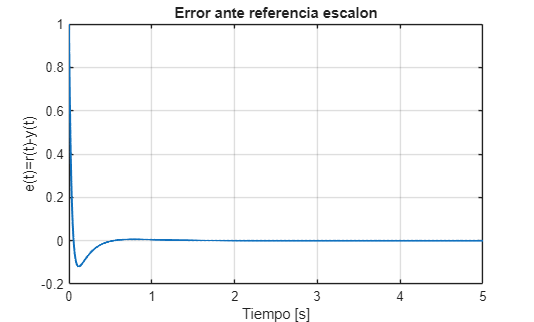


%% ============================================================
%  4) Errores de seguimiento
% ============================================================

figure;
plot(t, e_step, 'LineWidth', 1.5);
grid on;
title('Error ante referencia escalon');
xlabel('Tiempo [s]');
ylabel('e(t)=r(t)-y(t)');

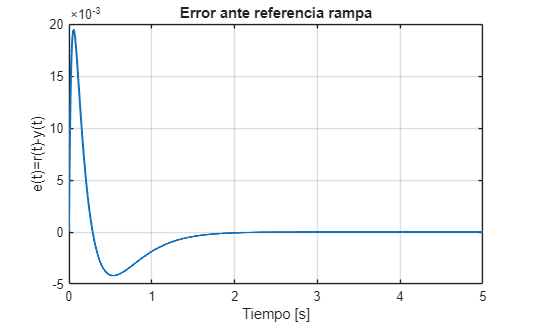


figure;
plot(t, e_ramp, 'LineWidth', 1.5);
grid on;
title('Error ante referencia rampa');
xlabel('Tiempo [s]');
ylabel('e(t)=r(t)-y(t)');

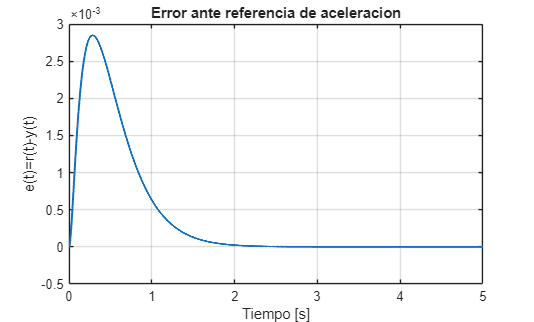


figure;
plot(t, e_acc, 'LineWidth', 1.5);
grid on;
title('Error ante referencia de aceleracion');
xlabel('Tiempo [s]');
ylabel('e(t)=r(t)-y(t)');


fprintf('\nErrores al final de la simulacion:\n');


Errores al final de la simulacion:


fprintf('Error escalon      = %.6e\n', e_step(end));

Error escalon      = 1.391296e-08


fprintf('Error rampa        = %.6e\n', e_ramp(end));

Error rampa        = 3.900149e-08


fprintf('Error aceleracion  = %.6e\n', e_acc(end));

Error aceleracion  = -1.365329e-07
